clear
clc

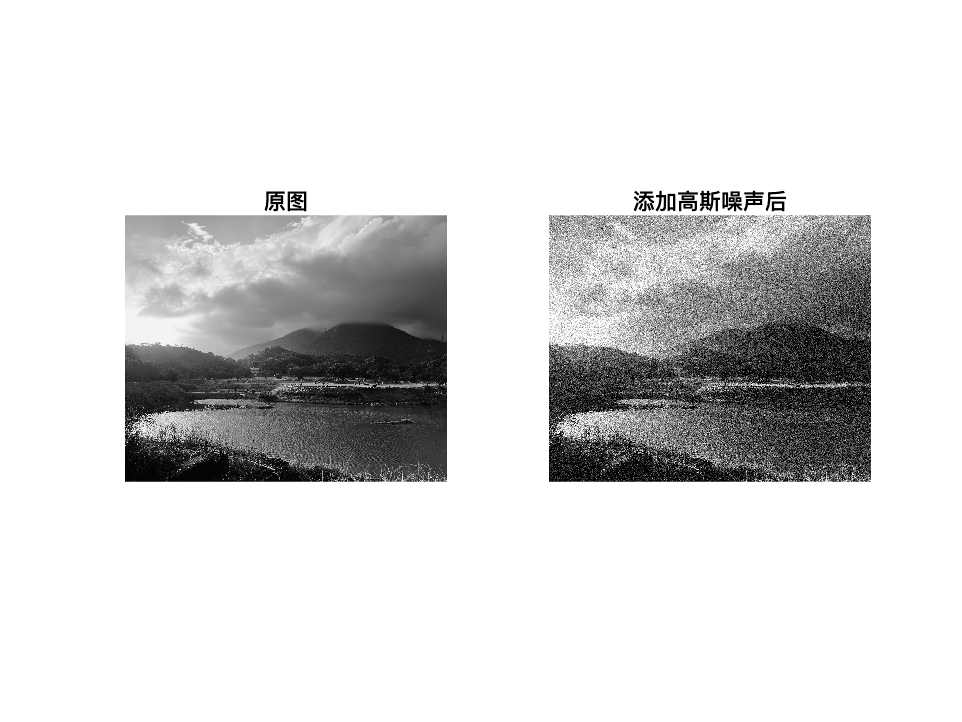

% 读取图片
originalImg = rgb2gray(imread('./风景.jpg'));

% 添加椒盐噪声
img = imnoise(originalImg, 'gaussian', 0, 0.03);

% 显示原始图片和添加噪声后的图片
figure
subplot(1,2,1), imshow(originalImg), title('原图');
subplot(1,2,2), imshow(img), title('添加高斯噪声后');

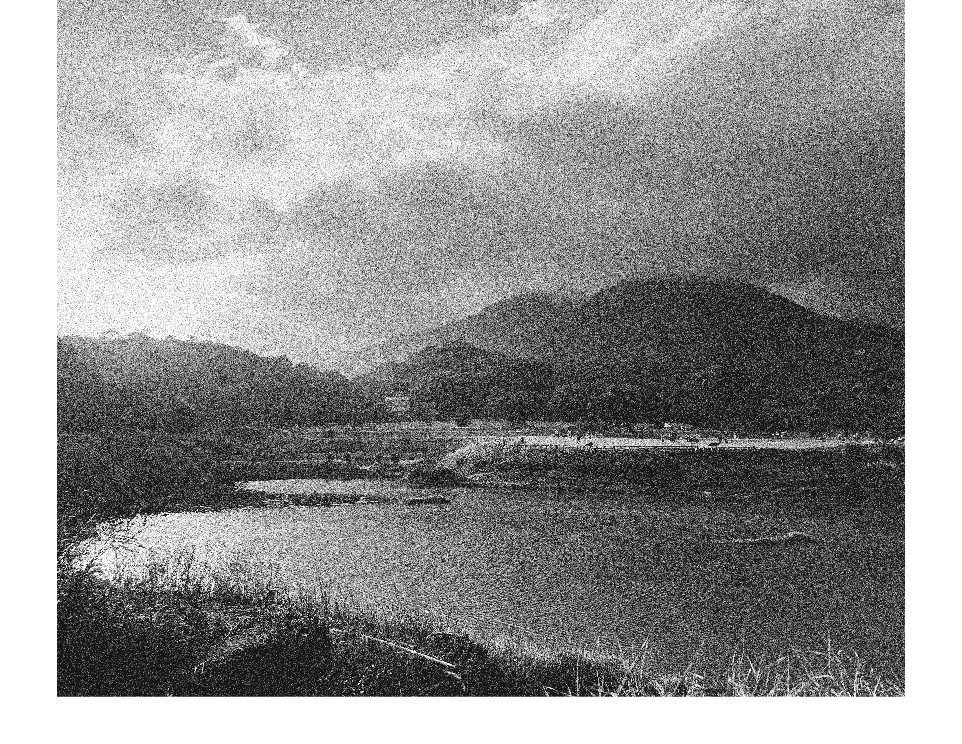

img1 = histeq(img,64);
figure, imshow(img1), title('直方图均衡化');

% 均值滤波
img2_1 = imfilter(img, fspecial('average',[3,3]))

img2_1 = 3024×3656 uint8 矩阵
    88   124   124   126   117   103    91    91    88    94    99   111    99   116   103    99    87    96   101    97    96   111   104   103    97   104    99   106   109   124   118   110    88    83    87    96   101   115   108   105    95   107   120   115   114   102    97    91   102   108
   105   161   173   187   180   165   154   147   148   143   137   141   131   160   149   151   139   153   153   156   161   175   162   152   147   155   151   172   174   182   166   156   149   131   141   142   164   176   168   154   144   147   161   156   155   155   148   145   151   157
   107   159   166   174   171   164   157   154   149   146   123   125   120   149   148   147   147   162   160   174   173   180   168   160   160   149   151   183   194   198   180   178   165   133   132   139   165   184   183   171   161   146   163   154   165   165   170   168   165   164
   100   154   159   168   165   165   169   160   161   144   126   

img2_2 = imfilter(img, fspecial('average',[5,5]))

img2_2 = 3024×3656 uint8 矩阵
    58    82   105   103   103   103    94    90    89    83    85    84    88    87    89    87    95    87    90    98    99    93    98    96    91    90   100    98   102   104   100    94    89    85    85    92    95    98    96    96    92    91    92    92    95    92    87    93    93    90
    79   112   142   139   138   139   129   124   124   111   111   109   111   110   115   114   124   116   122   133   134   127   136   128   122   121   132   131   141   146   143   134   125   117   113   117   125   130   130   132   126   124   122   124   126   128   123   132   132   125
   100   136   173   167   165   167   156   149   151   141   139   143   147   146   152   151   158   151   156   167   166   160   166   158   148   150   157   155   167   178   175   168   158   152   144   144   151   158   157   160   156   155   154   154   154   154   148   157   162   160
    92   127   163   158   160   165   155   150   158   147   144   

img2_3 = imfilter(img, fspecial('average',[7,7]))

img2_3 = 3024×3656 uint8 矩阵
    57    73    85    98    97    95    95    91    82    83    81    81    81    78    79    87    83    88    89    91    93    94    90    92    90    92    93    97    98    98    98    95    89    89    86    87    88    88    92    91    93    91    87    90    89    88    94    92    92    93
    69    89   103   119   119   115   113   111   102   104   103   103   105   104   104   112   110   112   114   114   116   118   112   112   111   111   112   116   118   120   121   116   113   112   108   107   107   107   113   110   113   112   109   111   109   107   113   113   114   117
    81   104   121   140   142   139   139   137   127   131   131   130   133   130   129   137   133   135   136   136   139   140   135   136   134   134   137   141   144   147   147   142   140   137   134   131   129   128   135   132   136   134   130   132   131   127   133   131   134   138
    94   119   138   159   164   161   163   159   151   156   157   

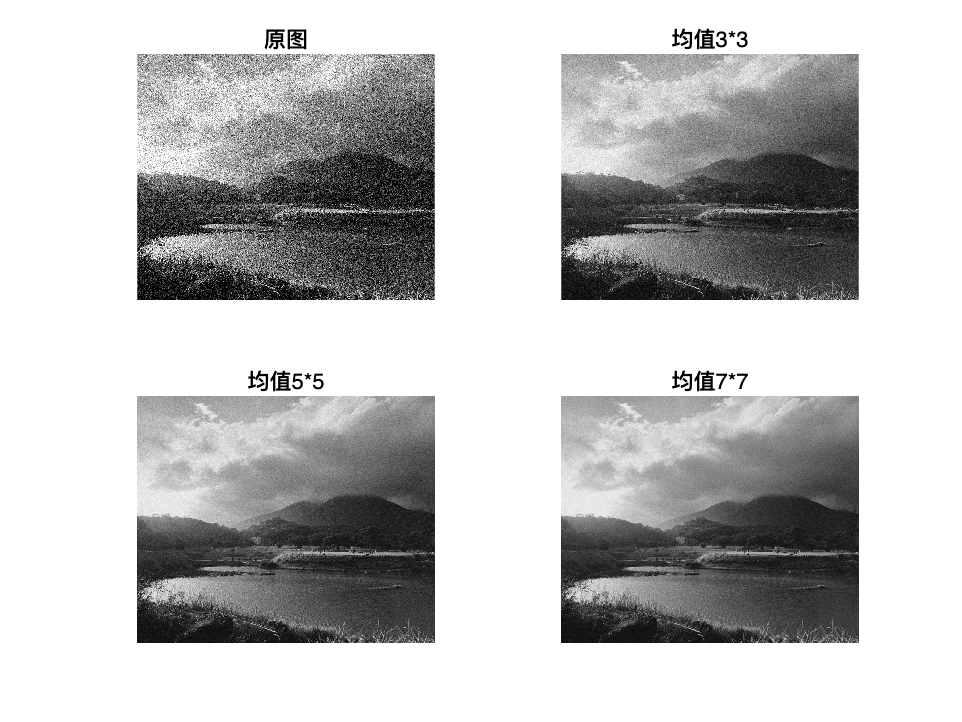

figure;
subplot(2,2,1), imshow(img),title('原图');
subplot(2,2,2), imshow(img2_1),title('均值3*3');
subplot(2,2,3), imshow(img2_2),title('均值5*5');
subplot(2,2,4), imshow(img2_3),title('均值7*7');

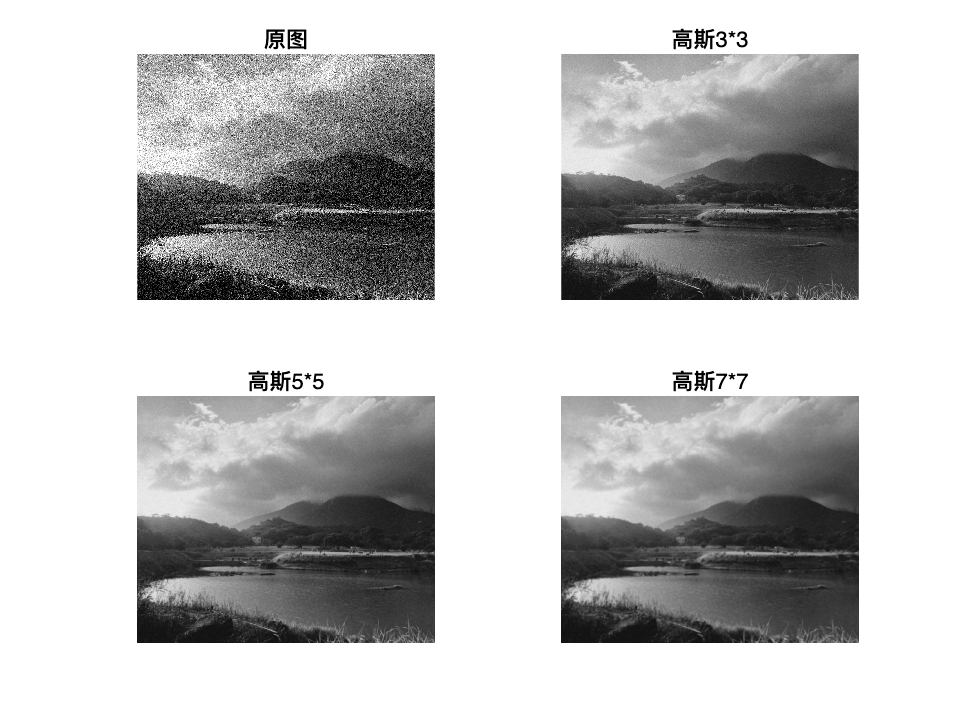

% 高斯滤波
img3_1 = imgaussfilt(img, [3, 3]);
img3_2 = imgaussfilt(img, [5, 5]);
img3_3 = imgaussfilt(img, [7, 7]);
figure;
subplot(2,2,1), imshow(img),title('原图');
subplot(2,2,2), imshow(img3_1),title('高斯3*3');
subplot(2,2,3), imshow(img3_2),title('高斯5*5');
subplot(2,2,4), imshow(img3_3),title('高斯7*7');

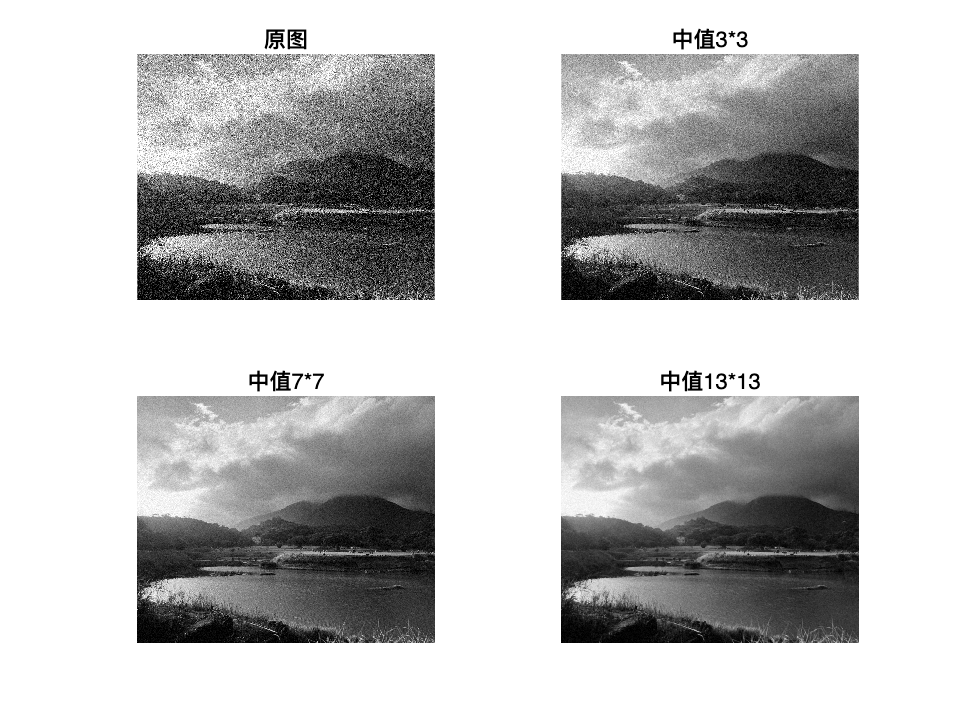

% 中值滤波
img4_1 = medfilt2(img(:,:,1), [3, 3]);
img4_2 = medfilt2(img(:,:,1), [7, 7]);
img4_3 = medfilt2(img(:,:,1), [13, 13]);
figure;
subplot(2,2,1), imshow(img),title('原图');
subplot(2,2,2), imshow(img4_1),title('中值3*3');
subplot(2,2,3), imshow(img4_2),title('中值7*7');
subplot(2,2,4), imshow(img4_3),title('中值13*13');